path = '/Users/platel/Desktop/exp/aurelie/444175_new/'

daytime = '23_11_22_08_35_03'

make new folder /Users/platel/Desktop/exp/analysis/23_11_22_08_35_03P2M_444175_221125_plane1_2023_01_09.09-19-4010cluster/


median normalization
sgolayfilter
Ncells= 361
Sum transient: 82392
nSCE: 383
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.
nClusters: 10


nClustersOK: 7
nSCEOK: 231
Elapsed time is 306.581906 seconds.


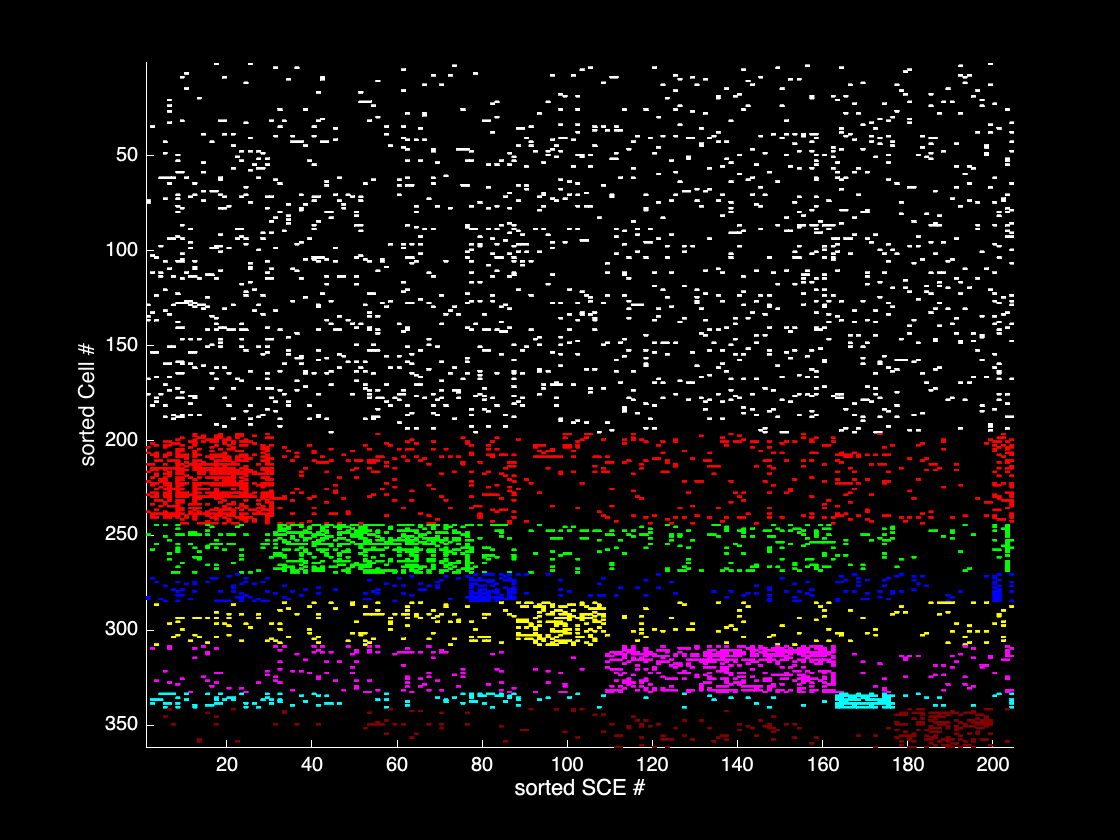

path = '/Users/platel/Desktop/exp/aurelie/444175_new/'

daytime = '23_11_22_08_40_35'

make new folder /Users/platel/Desktop/exp/analysis/23_11_22_08_40_35P2M_444175_221125_plane1_2023_01_09.09-19-4010cluster/


median normalization
sgolayfilter
Ncells= 361
Sum transient: 82392
nSCE: 383
nClusters: 10
nClustersOK: 8
nSCEOK: 297
Elapsed time is 283.557530 seconds.


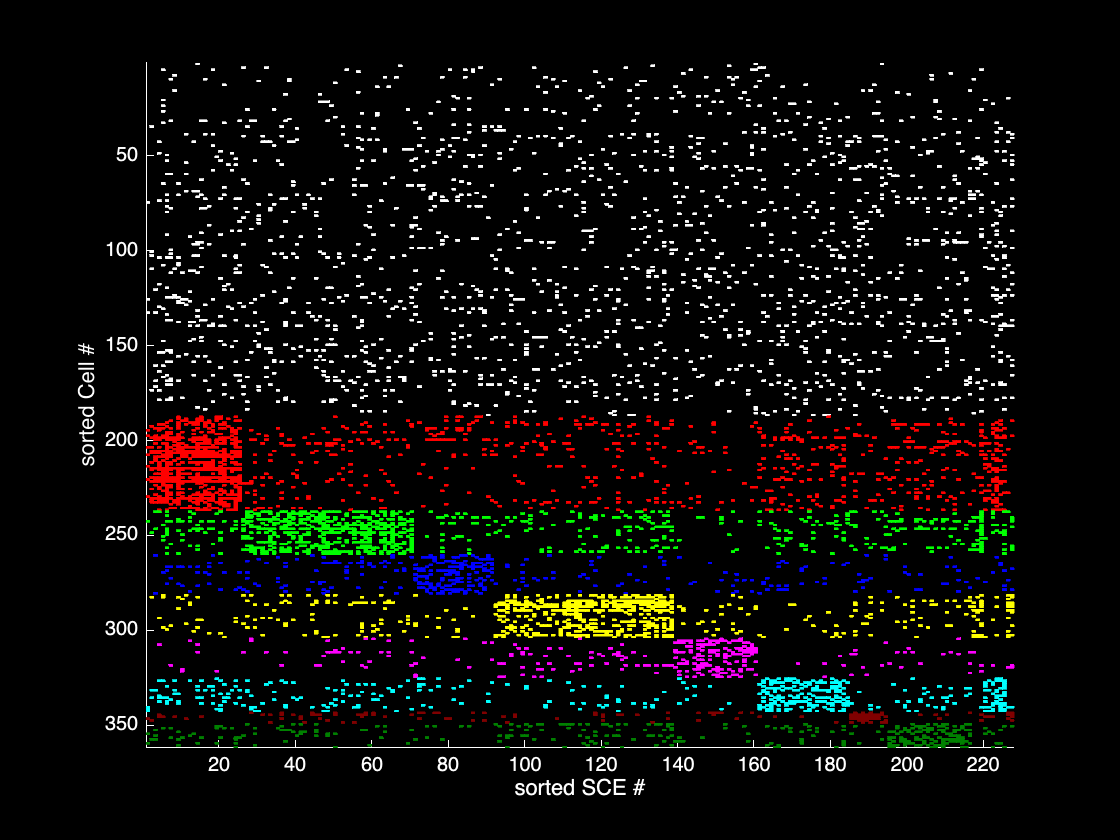

path = '/Users/platel/Desktop/exp/aurelie/444175_new/'

daytime = '23_11_22_08_45_46'

make new folder /Users/platel/Desktop/exp/analysis/23_11_22_08_45_46P2M_444175_221125_plane1_2023_01_09.09-19-4010cluster/


median normalization
sgolayfilter
Ncells= 361
Sum transient: 82392
nSCE: 383
nClusters: 10
nClustersOK: 7
nSCEOK: 244
Elapsed time is 305.155390 seconds.


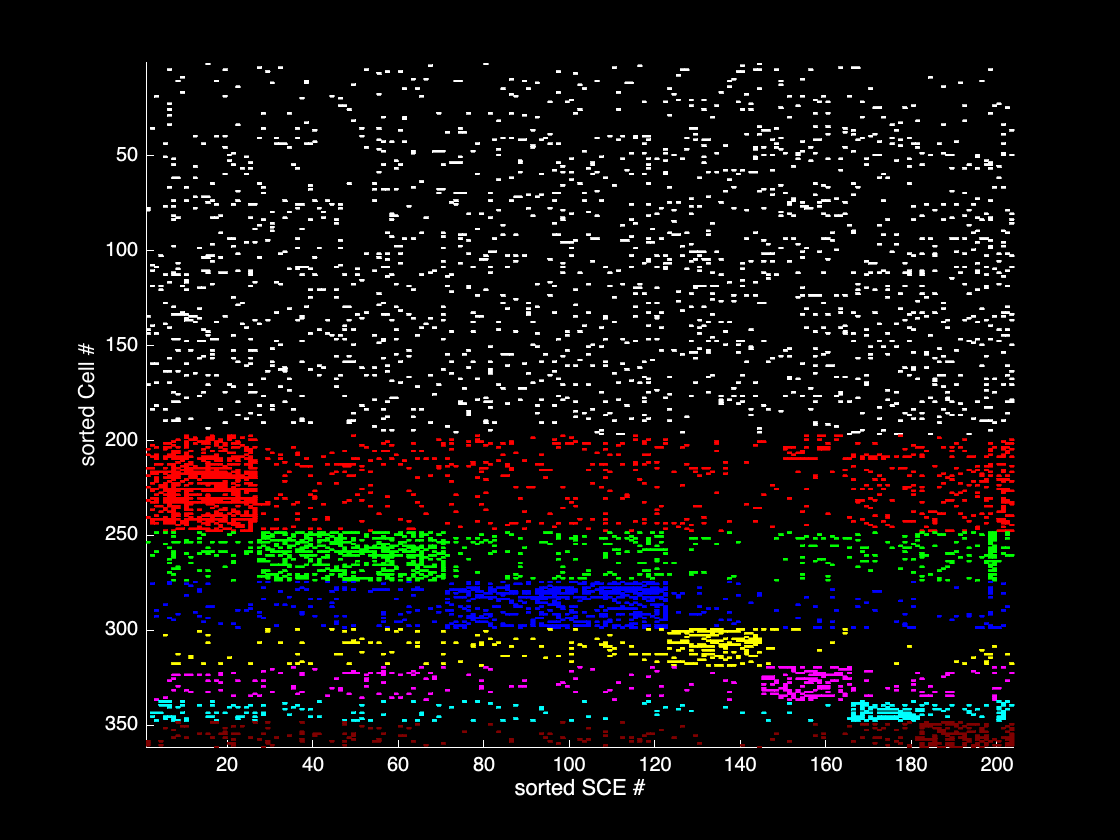

path = '/Users/platel/Desktop/exp/aurelie/444175_new/'

daytime = '23_11_22_08_51_18'

make new folder /Users/platel/Desktop/exp/analysis/23_11_22_08_51_18P2M_444175_221125_plane1_2023_01_09.09-19-4010cluster/


median normalization
sgolayfilter
Ncells= 361
Sum transient: 82392
nSCE: 383
nClusters: 10


clear
close all
% delete(gcp('nocreate'))
% parpool ('processes',40)


% Launch a file dialog box to select a file
% % [name, path] = uigetfile('*.nwb', 'Select a File');
% path='/Volumes/10.51.106.5/Data/Aurelie/brainbow analysis/444175/221125_plane0_bis/';
% name='P2M_444175_221125_plane0_2023_10_25.17-43-15.nwb';
% % Check if the user canceled the file selection
% if isequal(name, 0)
%     disp('User canceled file selection');
%     return
% else
% %     % Display the selected file's full path
%     disp(['Selected file: ' fullfile(path, name)]);
% end
% load('allnwb.mat')
% PathSave='E:\Data\analysis\';%PC
PathSave='/Users/platel/Desktop/exp/analysis/';%mac
% filename=[path name];

% for file_num=1:numel (nwbFiles)
% filename='/Volumes/10.51.106.5/Data/Aurelie/brainbow analysis/444175/221125_plane1/P2M_444175_221125_plane1_2023_01_09.09-19-40.nwb';%mac
filename='/Users/platel/Desktop/exp/aurelie/444175_new/P2M_444175_221125_plane1_2023_01_09.09-19-40.nwb';
for nanalysis=1:10
    clearvars -except file_num nwbFiles PathSave nanalysis filename
    % try
        % filename=cell2mat(nwbFiles(file_num));
        % filename='E:\Data\Aurelie\brainbow analysis\411582\230320_plane1\P2M_411582_230320_plane1_2023_04_05.17-57-09.nwb'
        % filename='E:\Data\Aurelie\brainbow analysis\444118\220915_plane1_000\P2M_444118_220915_000_plane1_2023_05_04.09-14-19.nwb';
        
        % filename='E:\Data\Aurelie\brainbowanalysis\444175\221125_plane1\P2M_444175_221125_plane1_2023_01_09.09-19-40.nwb';%PC
        % filename='/Users/platel/Downloads/P26D_230123_230208_16_230218_plane0_2023_10_31.15-26-41.nwb';
        [path,name,ext] = fileparts(filename);
        % load('/Users/platel/Desktop/exp/Arnaud VIncent/A529/20150224/suite2p/plane0/Fall.mat')
        % name='A529'
        % load('/Users/platel/Desktop/exp/Arnaud VIncent/A529/20150224/speed.mat')
        % path='/Volumes/10.51.106.5/Data/Aurelie/brainbow analysis/444175/221125_plane0_bis/';
        % name='P2M_444175_221125_plane0_2023_10_25.17-43-15.nwb';
        % path =[path '\']%pc
        path=[path '/']%mac
        % filename=[path name];
        daytime = datestr(now,'yy_mm_dd_HH_MM_SS')
        namefull=[PathSave daytime name '10cluster/'];
        mkdir (namefull)    % make folder for saving analysis
        disp(['make new folder ' namefull])
        
        openingnwb
        assembly_SCE5
        % NoCamp_DetectRace

        rastercolor
 % 
        exportdata
        save([namefull,'results.mat'])  
        % plotassembly
 %        brainbowassemblies2023_09_26
 %        distance_calculation
 %        export_data_brainbow
 %        save([namefull,'brainbow.mat']) 
 % 
 %    % catch exception
 %    %     disp(['An error occurred in: ' filename]);
 %    %     disp(exception.message);  % Display the error message
 %    %     disp('but analysis continue ;)')
 %    % end
 % 
end